# `Machine Learning Coursework - Classification Tree`

#### `Alessandro Alviani `

`City University, December 2021`

## `Data Preparation `

### `Importing the data`

train = readtable("train_eng_2.csv");
test = readtable('test_eng_2.csv');

### `Train and test set for crossvalidation`

rng(0)
cvp = cvpartition(train.Stay, "KFold", 5) % Kfolding on the training set to use for crossvalidation. 

cvp = K-fold cross validation partition
   NumObservations: 409816
       NumTestSets: 5
         TrainSize: 327853  327852  327853  327853  327853
          TestSize: 81963  81964  81963  81963  81963

## `Classification tree - untuned`

`The below section wants to be a quick implementation to check how an untuned tree would behave on the data.`

tic
Model = fitctree(train, 'Stay'); % untuned model 
% first line: model loss (1 - Accuracy), F1, Balanced Accuracy, Sensitivity
% second line: false negative rate, false positive rate, specificity, fdr
model_loss = loss(Model, test, 'Stay'); te_f1_score = f1(Model, test); te_balanced_accuracy = balanced_accuracy(Model, test); te_sen = sensitivity(Model,test);
te_false_neg = fnr(Model, test); te_false_pos = fpr(Model, test); te_spe = specificity(Model, test); fd_r = fdr(Model, test);
%display the test performance
disp("UNTUNED MODEL PERFORMANCE:"); disp("Loss = " + string(model_loss)); disp("F1 score = " + string(te_f1_score)); disp("Balanced accuracy = " + string(te_balanced_accuracy)); disp("Sensitivity= " + string(te_sen)); disp("False negative rate = " + string(te_false_neg));  disp("False positives rate = " + string(te_false_pos)); disp("Specificity = " + string(te_spe)); disp("False Discovery Rate = " + string(fd_r))

UNTUNED MODEL PERFORMANCE:
Loss = 0.18489
F1 score = 0.65096
Balanced accuracy = 0.81511
Sensitivity= 0.78034
False negative rate = 0.21966
False positives rate = 0.15011
Specificity = 0.84989
False Discovery Rate = 0.44162


toc

Elapsed time is 0.684703 seconds.


## `Tuning the Tree classifier`

`In the sections below we tune the tree and try to address the main problems we have encountered in the intermediate phases of this work. These are mostly two:`

- `Our tree overfits the training set and fails to generalize on the test set. `

- `The model has a very high false dsicovery rate.  `

`Trees have many parameters that can be controlled, probabily the most importants are the ones that control their depth. These parameters are the main contributors in helping reduce the variance of the tree. `

`To study the behaviour of our model on the train set we use Kfold crossvalidation, this is useful to optimise the hyperparameters while avoiding (or reducing) overfitting. `

### `Depth parameters - Maximum number of splits - Crossvalidation`

`By default this parameter is n - 1 where n is the number of samples. In our study the tree could potentially split into 409815 branche if not controlled. `

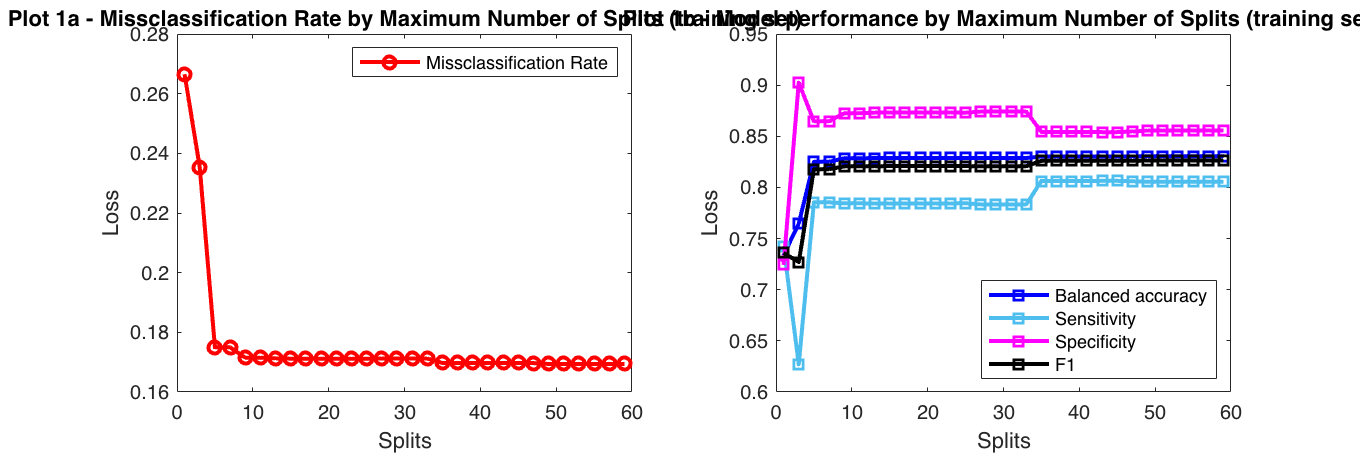

splits = (1:2:60); % sets the maximum number of splits to test
kloss = zeros(1, numel(splits)); % store kloss here
b_a_training = zeros(1, numel(splits)); % store balanced accuracy 
se_training = zeros(1, numel(splits)); % store model sensitivity 
sp_training = zeros(1, numel(splits)); % store model specificity 
f1_training = zeros(1, numel(splits)); % store model specificity 
figure;
for split = 1:length(splits)
    CT_mdl = fitctree(train, 'Stay', 'CVPartition', cvp, 'MaxNumSplits', splits(split)); % crossvalidates the tree on 10 folds
    kloss(split) = kfoldLoss(CT_mdl);
    b_a_training(split) = kfold_balanced_accuracy(CT_mdl, train); %balanced accuracy
    se_training(split) = kfold_sensitivity(CT_mdl, train); % sensitivity
    sp_training(split) = kfold_specificity(CT_mdl, train); % specificity
    f1_training(split) = kfold_f1(CT_mdl, train); % f1

end

% plots 
figure;
set(gcf,'position',[10, 10 , 3000 , 1000]) 
%subplot 1
subplot(1,2,1)
plot(splits, kloss, '-or', 'LineWidth',2);
hold on;
title('Plot 1a - Missclassification Rate by Maximum Number of Splits (training set)');
xlabel('Splits');
ylabel('Loss');
legend('Missclassification Rate');
hold off;
%subplot 2
subplot(1,2,2)
plot(splits, b_a_training, '-sb', 'LineWidth',2);
hold on;
plot(splits, se_training, '-s', 'LineWidth',2, Color='#4DBEEE');
plot(splits, sp_training, '-s', 'LineWidth',2, Color='magenta');
plot(splits, f1_training, '-s', 'LineWidth',2, Color='black');
title('Plot 1b - Model performance by Maximum Number of Splits (training set) ');
xlabel('Splits');
ylabel('Loss');
legend('Balanced accuracy', 'Sensitivity', "Specificity", 'F1', 'Location','southeast');
hold off;

### `Depth parameters - Maximum number of splits - Training vs Test set `

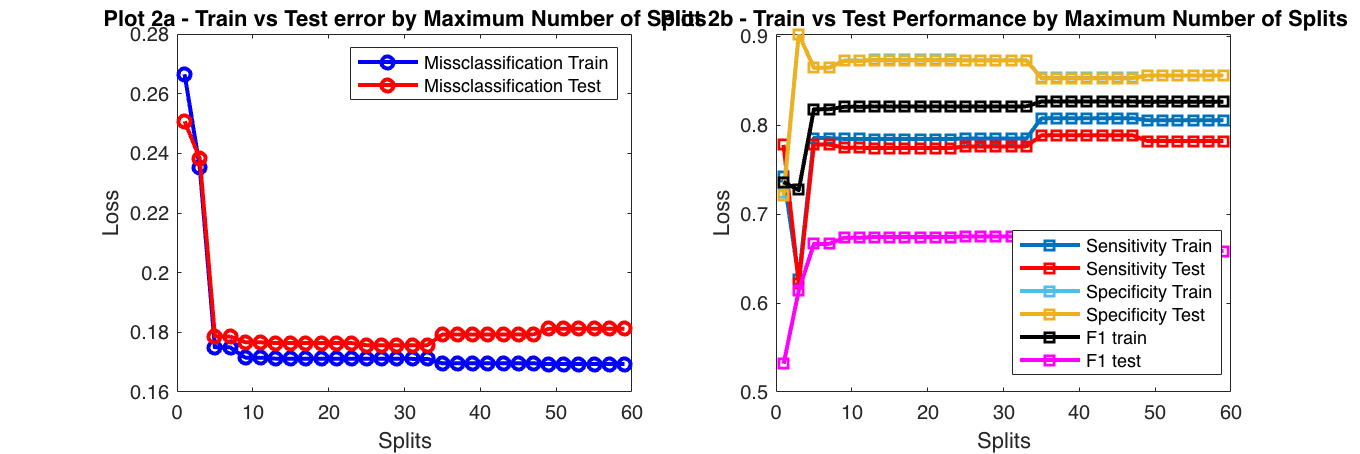

splits = (1:2:60); % control number of splits
mloss = zeros(1, numel(splits)); % store kloss 
t_loss = zeros(1, numel(splits)); % store test set loss 
se_training = zeros(1, numel(splits)); % store sensitivity training set 
se_test = zeros(1, numel(splits)); % store sensitivity test set
sp_training = zeros(1, numel(splits)); % store train set specificity 
sp_test = zeros(1, numel(splits)); % store test set sensitivity
f1_training = zeros(1, numel(splits)); % f1 train
f1_test = zeros(1, numel(splits)); % f1 test
figure;
for split = 1:length(splits)
    CT_mdl = fitctree(train, 'Stay', 'MaxNumSplits', splits(split)); % model 
    mloss(split) = loss(CT_mdl, train, 'Stay'); %train loss
    t_loss(split) = loss(CT_mdl, test, 'Stay'); % test loss 
    se_training(split) = sensitivity(CT_mdl, train); % tain sensitivity 
    se_test(split) = sensitivity(CT_mdl, test); % test sensitivity 
    sp_training(split) = specificity(CT_mdl, train); % trainining specificity
    sp_test(split) = specificity(CT_mdl, test); % test specificity 
    f1_training(split) = f1(CT_mdl, train); % trainining specificity
    f1_test(split) = f1(CT_mdl, test); % test specificity 
end
%plots 
figure;
set(gcf,'position',[10, 10 , 3000 , 1000])
% subplot 1
subplot(1,2,1)
plot(splits, mloss, '-ob', 'LineWidth',2);
hold on;
plot(splits, t_loss, '-or', 'LineWidth',2);
title('Plot 2a - Train vs Test error by Maximum Number of Splits');
xlabel('Splits');
ylabel('Loss');
legend('Missclassification Train','Missclassification Test');
hold off;
% subplot 2 
subplot(1,2,2)
plot(splits, se_training, '-s', 'LineWidth',2, Color='#0072BD');
hold on;
plot(splits, se_test, '-sr', 'LineWidth',2);
plot(splits, sp_training, '-s', 'LineWidth',2, Color='#4DBEEE');
plot(splits, sp_test, '-s', 'LineWidth',2, Color='#EDB120');
plot(splits, f1_training, '-s', 'LineWidth',2, Color='black');
plot(splits, f1_test, '-s', 'LineWidth',2, Color='magenta');
title('Plot 2b - Train vs Test Performance by Maximum Number of Splits');
xlabel('Splits');
ylabel('Loss');
legend('Sensitivity Train', 'Sensitivity Test','Specificity Train','Specificity Test', 'F1 train', 'F1 test', 'Location','best');
hold off;

### `Depth parameters - ` `Minimum leaf size - Crossvalidation`

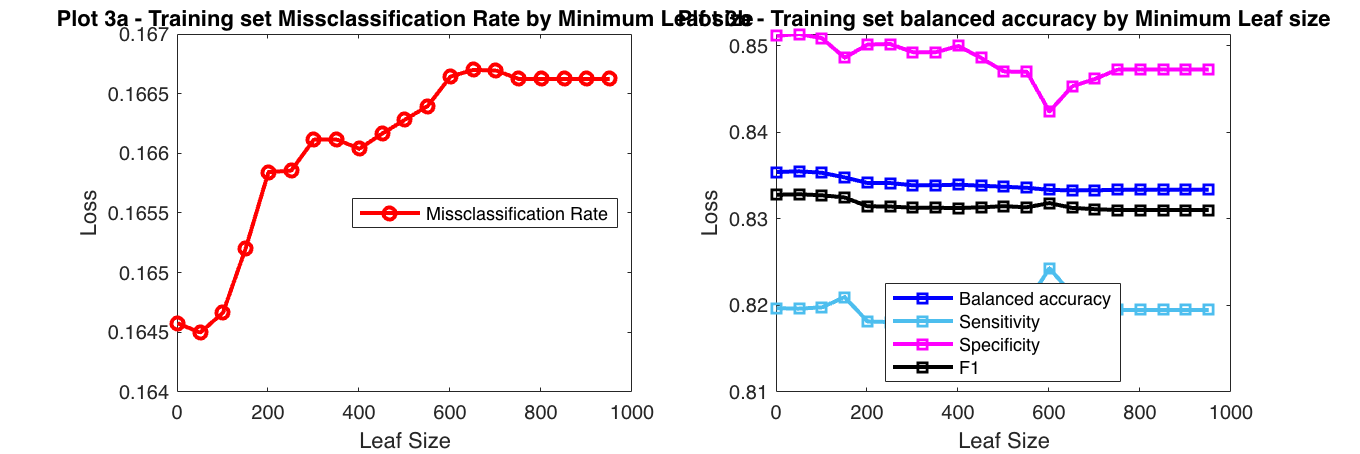

leaf_size = (1:50:1000); % control leaf size
kloss = zeros(1, numel(leaf_size)); % store loss here
b_a_training = zeros(1, numel(leaf_size)); % store balanced accuracy 
se_training = zeros(1, numel(leaf_size)); % store model sensitivity 
sp_training = zeros(1, numel(leaf_size)); % store model specificity 
f1_training = zeros(1, numel(leaf_size)); % store model f1 

for leaf = 1:length(leaf_size)
    CT_mdl = fitctree(train, 'Stay', 'CVPartition',cvp, 'MinLeafSize', leaf_size(leaf)); % crossvalidated model 
    kloss(leaf) = kfoldLoss(CT_mdl); %kfold loss 
    b_a_training(leaf) = kfold_balanced_accuracy(CT_mdl, train); %model balanced accuracy 
    se_training(leaf) = kfold_sensitivity(CT_mdl, train); % model sensitivity 
    sp_training(leaf) = kfold_specificity(CT_mdl, train); % model specificity
    f1_training(leaf) = kfold_f1(CT_mdl, train); % model specificity 

end

figure;
set(gcf,'position',[10, 10 , 3000 , 1000])
%subplot 1 
subplot(1,2,1)
plot(leaf_size, kloss, '-or', 'LineWidth',2);
title('Plot 3a - Training set Missclassification Rate by Minimum Leaf size');
xlabel('Leaf Size');
ylabel('Loss');
legend('Missclassification Rate', 'Location','east');
% subplot 2
subplot(1,2,2)
plot(leaf_size, b_a_training, '-sb', 'LineWidth',2);
hold on;
plot(leaf_size, se_training, '-s', 'LineWidth',2, Color='#4DBEEE');
plot(leaf_size, sp_training, '-s', 'LineWidth',2, Color='magenta');
plot(leaf_size, f1_training, '-s', 'LineWidth',2, Color='black');
title('Plot 3b - Training set balanced accuracy by Minimum Leaf size');
xlabel('Leaf Size');
ylabel('Loss');
legend('Balanced accuracy', 'Sensitivity', 'Specificity', 'F1', 'Location','best' );
hold off;

`The above plot may be missleading - in fact in this model we haven't set any limit to the number of splits and despite we try to control the minimum leaf size the model is still overfitting the train set. `

### `Depth parameters - ` `Minimum leaf size - Training vs Test set`

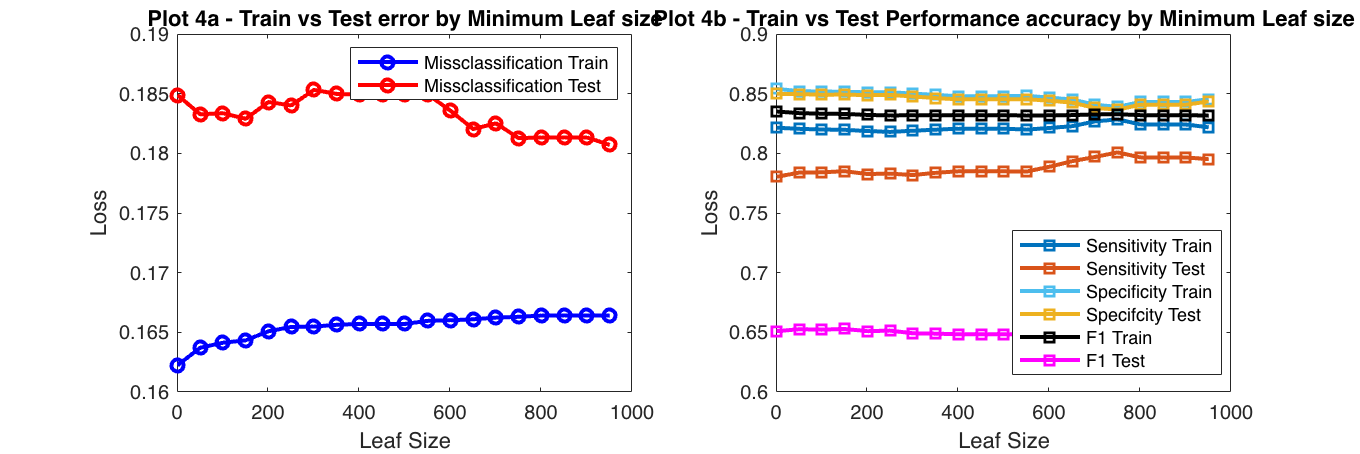

leaf_size = (1:50:1000); % control leaf size range
mloss = zeros(1, numel(leaf_size)); 
t_loss = zeros(1, numel(leaf_size)); 
se_tr = zeros(1, numel(leaf_size)); % store sensitivity train
se_test = zeros(1, numel(leaf_size)); % store sensitivity test
sp_tr = zeros(1, numel(leaf_size)); % store specificity train
sp_test = zeros(1, numel(leaf_size)); % store specificity test
f1_tr = zeros(1, numel(leaf_size)); % store f1 train
f1_test = zeros(1, numel(leaf_size)); % store f1 test

for leaf = 1:length(leaf_size)
    CT_mdl = fitctree(train, 'Stay', 'MinLeafSize', leaf_size(leaf)); %model 
    mloss(leaf) = loss(CT_mdl, train, 'Stay'); %train loss 
    t_loss(leaf) = loss(CT_mdl, test, 'Stay'); %test loss 
    se_tr(leaf) = sensitivity(CT_mdl, train); %sensitivity train
    se_test(leaf) = sensitivity(CT_mdl, test); %sensitivity test
    sp_tr(leaf) = specificity(CT_mdl, train); % f1 train
    sp_test(leaf) = specificity(CT_mdl, test); % f1 test
    f1_tr(leaf) = f1(CT_mdl, train); % f1 train
    f1_test(leaf) = f1(CT_mdl, test); % f1 test
end

figure;
set(gcf,'position',[10, 10 , 3000 , 1000])
% subplot 1 
subplot(1,2,1)
plot(leaf_size, mloss, '-ob', 'LineWidth',2);
hold on;
plot(leaf_size, t_loss, '-or', 'LineWidth',2);
title('Plot 4a - Train vs Test error by Minimum Leaf size');
xlabel('Leaf Size');
ylabel('Loss');
legend('Missclassification Train','Missclassification Test');
hold off;
% subplot 2 
subplot(1,2,2)
plot(leaf_size, se_tr, '-s', 'LineWidth',2, Color='#0072BD');
hold on;
plot(leaf_size, se_test, '-s', 'LineWidth',2);
plot(leaf_size, sp_tr, '-s', 'LineWidth',2, Color='#4DBEEE');
plot(leaf_size, sp_test, '-s', 'LineWidth',2, Color='#EDB120');
plot(leaf_size, f1_tr, '-s', 'LineWidth',2, Color='black');
plot(leaf_size, f1_test, '-s', 'LineWidth',2, Color='magenta');
title('Plot 4b - Train vs Test Performance accuracy by Minimum Leaf size');
xlabel('Leaf Size');
ylabel('Loss');
legend('Sensitivity Train', 'Sensitivity Test', 'Specificity Train', 'Specifcity Test','F1 Train','F1 Test', 'Location','best');
hold off;

#### `Considerations`

`The above plots show the influence of Maximum Number of Splits and Minimum leaf size on the tree performance. As these parameters are tuned the tree stops to overfit and generalize better.  `

`To notice how sensitivty and specificity may tend to move in opposite directions. `

`In the next section we tune the Maximum Number of Splits and Minimum Leaf Size in conjunction. `

## `Grid Search Hyperparameters optimisation `

`Matlab offers a convenient Grid Search implementation that allows us to tune all the main hyperparameters in a quick and efficient way.`

rng(0);%for reproducibility

MaxNumSplit = optimizableVariable('MaxNumSplit',[1,30],'Type','integer'); % sets the range of our parameter
MinLeaf = optimizableVariable('MinLeaf',[1,500],'Type','integer'); % sets the range of our parameter
hyperparamtersRF = [MaxNumSplit;MinLeaf];
% setting the "right" known priors makes the biggest differece to this model.
opts = struct('Optimizer','bayesopt','ShowPlots',false,'AcquisitionFunctionName','expected-improvement-plus','verbose',1, 'CVPartition', cvp);
Model = fitctree(train,'Stay', 'OptimizeHyperparameters',hyperparamtersRF,'HyperparameterOptimizationOptions',opts);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |      MinLeaf |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.17151 |     0.76537 |     0.17151 |     0.17151 |           16 |          499 |
|    2 | Accept |     0.17151 |     0.55461 |     0.17151 |     0.17151 |            9 |          291 |
|    3 | Accept |     0.17151 |     0.52691 |     0.17151 |     0.17151 |            8 |           16 |
|    4 | Best   |     0.17117 |     0.62237 |     0.17117 |     0.17117 |           25 |           98 |
|    5 | Accept |     0.17122 |     0.63427 |     0.17117 |     0.17117 |           30 |            4 |
|    6 | Accept |     0.17162 |     0.57911 |     0.17117 |     

## `Model Performance on test set `

% first line: model loss (1 - Accuracy), F1, Balanced Accuracy, Sensitivity
% second line: false negative rate, false positive rate, specificity, fdr
model_loss = loss(Model, test, 'Stay'); te_f1_score = f1(Model, test); te_balanced_accuracy = balanced_accuracy(Model, test); te_sen = sensitivity(Model,test);
te_false_neg = fnr(Model, test); te_false_pos = fpr(Model, test); te_spe = specificity(Model, test); fd_r = fdr(Model, test);
%display the test performance
disp("TUNED MODEL PERFORMANCE:"); disp("Loss = " + string(model_loss)); disp("F1 score = " + string(te_f1_score)); disp("Balanced accuracy = " + string(te_balanced_accuracy)); disp("Sensitivity= " + string(te_sen)); disp("False negative rate = " + string(te_false_neg));  disp("False positives rate = " + string(te_false_pos)); disp("Specificity = " + string(te_spe)); disp("False Discovery Rate = " + string(fd_r))

TUNED MODEL PERFORMANCE:
Loss = 0.17569
F1 score = 0.67493
Balanced accuracy = 0.82431
Sensitivity= 0.77592
False negative rate = 0.22408
False positives rate = 0.12729
Specificity = 0.87271
False Discovery Rate = 0.4028


`This model does better than the original at most of its metrics. `

## `Confusion Matrix - Training and Test set comparison`

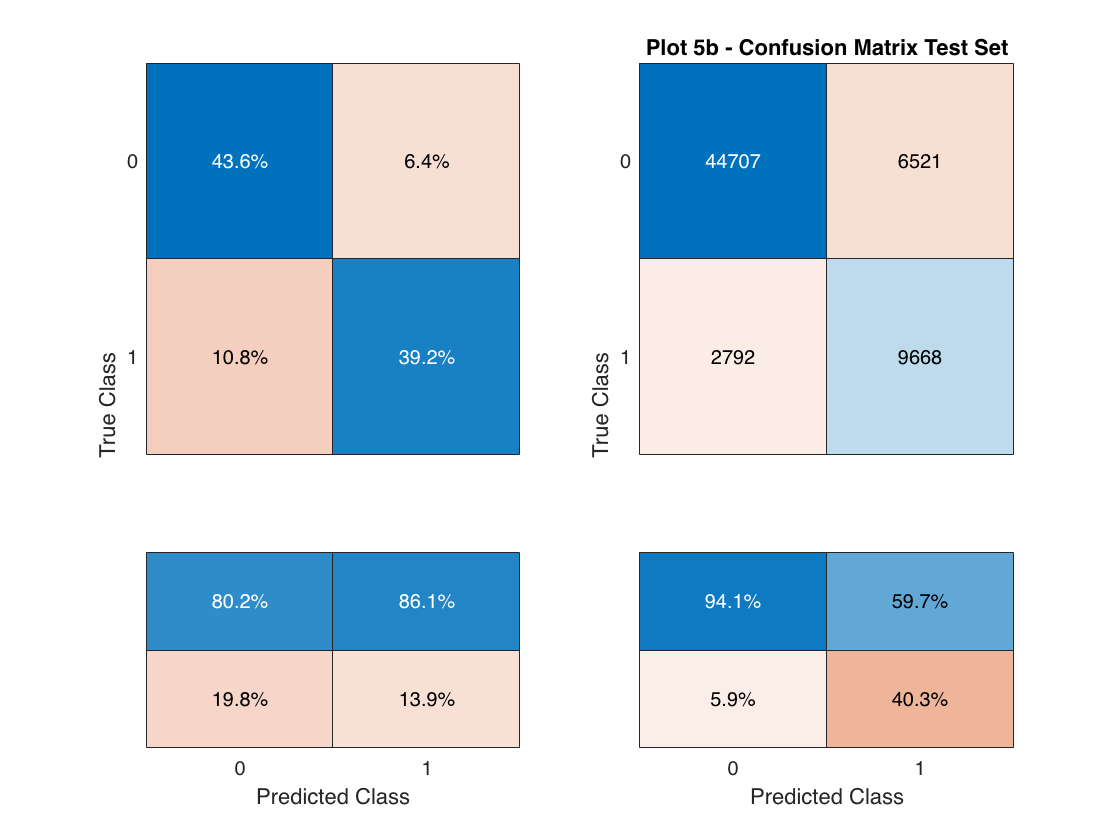

labels = predict(Model, train); % predicted labels 
figure();
subplot(1,2,1)
conf_chart = confusionchart(train.Stay, labels, 'Normalization','total-normalized', 'ColumnSummary','column-normalized'); % confusion chart
conf_chart_1.Title = "Plot 5a - Confusion Matrix Training Set";
labels = predict(Model, test); % predicted labels 
subplot(1,2,2)
conf_chart_3 = confusionchart(test.Stay, labels, 'Normalization','absolute', 'ColumnSummary','column-normalized'); % confusion chart
conf_chart_3.Title = "Plot 5b - Confusion Matrix Test Set";

`The above Confusion Matrix, namely the one on the right (Test Set) is why since the beginning we checked our model against a few metrics of unbalanced accuracy, especially the F1. Our model in fact is quite accurate overall but tends to get a high percentage of false postives.`

## `Prior Probabilities - Train and Test set`

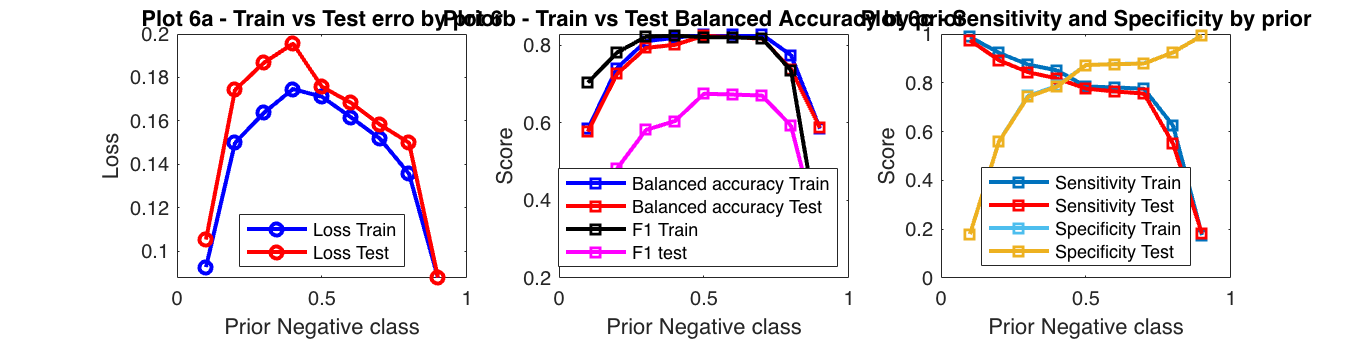

prior_x = [0.9:-0.1:0.1]; % prior probabilty for class 0 (Negative / "Short Stay")
prior_y = [0.1:0.1:0.9]; % prior probabilty for class 1 (Positive/ "Long Stay")
train_loss = zeros(1, numel(prior_x)); % store train here
test_loss = zeros(1, numel(prior_x)); % store test loss
train_ba = zeros(1, numel(prior_x));  % store train balanced accuracy 
test_ba = zeros(1, numel(prior_x));  % store test balanced accuracy 
train_se = zeros(1, numel(prior_x)); % store train sensitivity
test_se = zeros(1, numel(prior_x)); % store test sensitivity
train_sp= zeros(1, numel(prior_x)); % store train specificity
test_sp = zeros(1, numel(prior_x)); % store train specificity
train_f1= zeros(1, numel(prior_x)); % store train f1
test_f1= zeros(1, numel(prior_x)); % store train f1

for i  = 1:length(prior_x)
    prior = [prior_x(i), prior_y(i)];
    Model = fitctree(train, 'Stay','MaxNumSplits', 30, 'MinLeafSize', 4, 'Prior', prior);
    train_loss(i) = loss(Model, train, 'Stay'); % train loss
    test_loss(i) = loss(Model, test, 'Stay'); % test loss 
    train_ba(i) = balanced_accuracy(Model, train); % train balanced accuracy
    test_ba(i) = balanced_accuracy(Model, test); % test balanced accuracy
    train_f1(i) = f1(Model, train); % train f1
    test_f1(i) = f1(Model, test); % test f1
    train_se(i) = sensitivity(Model, train); % train sensitivity
    test_se(i) = sensitivity(Model, test); % train specificity
    train_sp(i) = specificity(Model, train); % train specificity
    test_sp(i) = specificity(Model, test); % test specificity

end

figure();
set(gcf,'position',[10, 10 , 3000 , 750]);
% subplot 1 
subplot(1,3,1);
plot(prior_x, train_loss, '-ob', 'LineWidth',2);
hold on;
plot(prior_x, test_loss, '-or', 'LineWidth',2);
title('Plot 6a - Train vs Test erro by prior');
xlabel('Prior Negative class');
ylabel('Loss');
legend('Loss Train','Loss Test', 'Location','south');
% subplot 2 
subplot(1,3,2);
plot(prior_x, train_ba, '-sb', 'LineWidth',2);
hold on;
plot(prior_x, test_ba, '-sr', 'LineWidth',2);
plot(prior_x, train_f1, '-sr', 'LineWidth',2, Color='black');
plot(prior_x, test_f1, '-sr', 'LineWidth',2, Color='magenta');
title('Plot 6b - Train vs Test Balanced Accuracy by prior');
xlabel('Prior Negative class');
ylabel('Score');
legend('Balanced accuracy Train', 'Balanced accuracy Test', 'F1 Train','F1 test', 'Location','south');
% subplot 3
subplot(1,3,3);
plot(prior_x, train_se, '-sb', 'LineWidth',2, Color ='#0072BD');
hold on;
plot(prior_x, test_se, '-sr', 'LineWidth',2);
plot(prior_x, train_sp, '-sr', 'LineWidth',2, Color='#4DBEEE');
plot(prior_x, test_sp, '-sr', 'LineWidth',2, Color='#EDB120');

title('Plot 6c - Sensitivity and Specificity by prior');
xlabel('Prior Negative class');
ylabel('Score');
legend('Sensitivity Train', 'Sensitivity Test','Specificity Train', 'Specificity Test', 'Location','best');

`The above plot show the effect of different priors on model performance. `

`70/30 (negative/positive) would seem a good split but in reality this would be matter of what we are interested in the most. Priors putting more weigth on the negative class would lead to better accuracy and better specificity but after a certain point (around 70-80%) they will severely affect F1 and sensitivity. The chosen prior in this case (70/30) offers the best balanced model. `

## `Spltting criterion `

`By default the tree uses the Gini's diversity index to split. `

criterions = ["gdi", "twoing", "deviance"];
for i = 1:length(criterions)
    CT_mdl = fitctree(train, 'Stay', 'CVPartition',cvp, 'MaxNumSplits', 30, 'MinLeaf', 4, 'SplitCriterion', criterions(i), 'Prior', [0.7, 0.3] ); % this is our "base" tree model
    disp("Crossvalidation loss with " + string(criterions(i)) + " = " + string(kfoldLoss(CT_mdl)));
    disp("Balanced accuracy with " + string(criterions(i)) + " = " + string(kfold_balanced_accuracy(CT_mdl, train)));
end 

Crossvalidation loss with gdi = 0.15181


Balanced accuracy with gdi = 0.82742


Crossvalidation loss with twoing = 0.15181


Balanced accuracy with twoing = 0.82742


Crossvalidation loss with deviance = 0.15346


Balanced accuracy with deviance = 0.82877


`No difference in splitting criterions. `

## `Tuning the model with a different prior and on a custom loss function (F1 score)`

`The loss function used to make this tuning can be found at the end of the page. `

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |      MinLeaf |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.17941 |      1.5277 |     0.17941 |     0.17941 |           19 |          100 |
|    2 | Accept |     0.17941 |      1.4654 |     0.17941 |     0.17941 |           10 |           60 |
|    3 | Accept |     0.17941 |       1.272 |     0.17941 |     0.17941 |            9 |            8 |
|    4 | Accept |     0.18202 |      1.6136 |     0.17941 |     0.17941 |           29 |           23 |
|    5 | Accept |      0.2641 |     0.72442 |     0.17941 |     0.17941 |            1 |           99 |
|    6 | Accept |     0.18203 |      1.4457 |     0.17941 |     

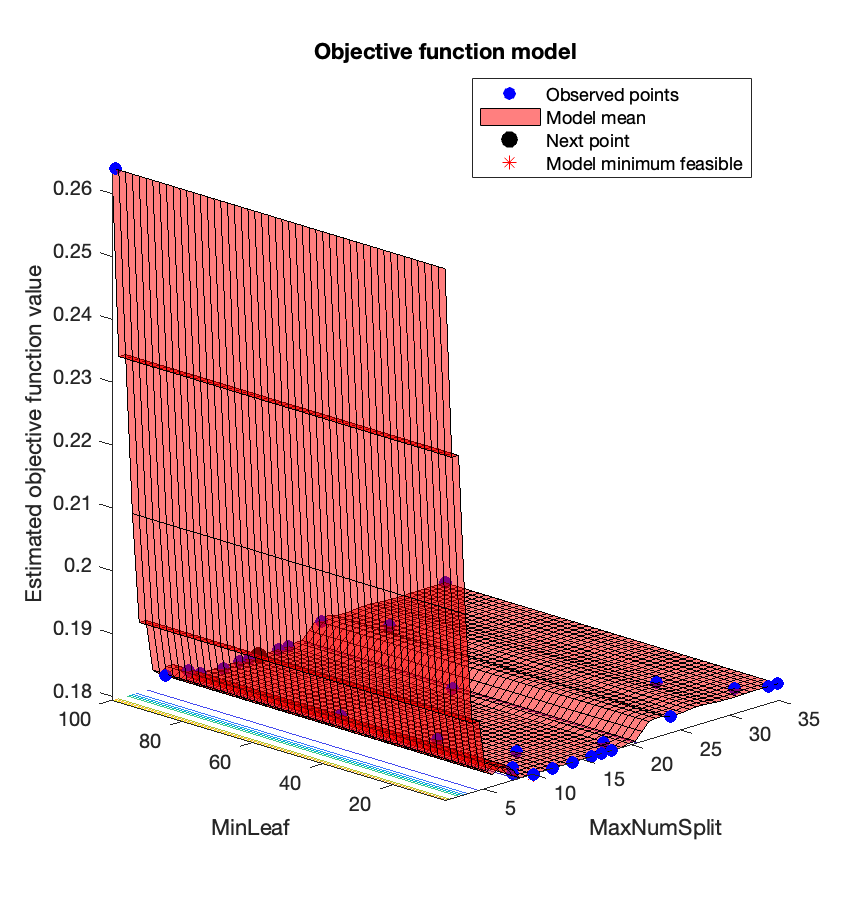

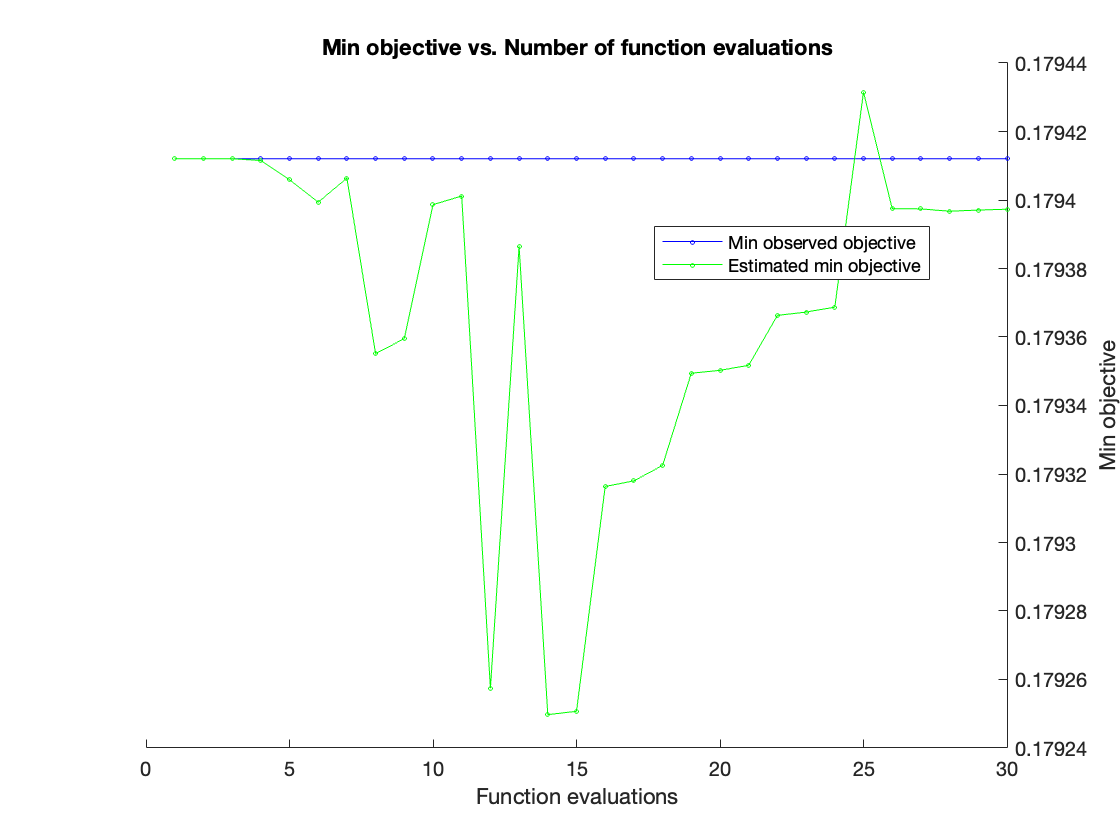


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 58.9062 seconds
Total objective function evaluation time: 40.2607

Best observed feasible point:
    MaxNumSplit    MinLeaf
    ___________    _______

        19           100  

Observed objective function value = 0.17941
Estimated objective function value = 0.1794
Function evaluation time = 1.5277

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeaf
    ___________    _______

        10           60   

Estimated objective function value = 0.1794
Estimated function evaluation time = 1.2316



rng(0)
% Variables for optimization and their range
MaxNumSplit = optimizableVariable('MaxNumSplit',[1,35],'Type','integer'); % Max num of splits range
MinLeaf = optimizableVariable('MinLeaf',[5,100],'Type','integer'); % Min leaf range
hyperparamtersRF = [MaxNumSplit;MinLeaf];

c_loss = @(params)f1_bayes(params, train, 'Stay'); % custom loss function (trains a 10 fold crossvalidated tree minimizing the false negative rate).
results = bayesopt(c_loss,hyperparamtersRF,'AcquisitionFunctionName','expected-improvement-plus', 'Verbose',1);

## `Final model`

`This is the final model and its metrics`

tic
Model_T = fitctree(train, 'Stay','MaxNumSplits', 10, 'MinLeafSize', 60, 'Prior', [0.70, 0.30]); 
% first line: model loss (1 - Accuracy), F1, Balanced Accuracy, Sensitivity
% second line: false negative rate, false positive rate, specificity, fdr
model_loss_T = loss(Model_T, test, 'Stay'); te_f1_score_T = f1(Model_T, test); te_balanced_accuracy_T = balanced_accuracy(Model_T, test); te_sen_T = sensitivity(Model_T,test);
te_false_neg_T = fnr(Model_T, test); te_false_pos_T = fpr(Model_T, test); te_spe_T = specificity(Model_T, test); fd_r_T = fdr(Model_T, test);
%display the test performance
disp("TUNED MODEL PERFORMANCE:"); disp("Loss = " + string(model_loss_T)); disp("F1 score = " + string(te_f1_score_T)); disp("Balanced accuracy = " + string(te_balanced_accuracy_T)); disp("Sensitivity= " + string(te_sen_T)); disp("False negative rate = " + string(te_false_neg_T));  disp("False positives rate = " + string(te_false_pos_T)); disp("Specificity = " + string(te_spe_T)); disp("False Discovery Rate = " + string(fd_r_T));

TUNED MODEL PERFORMANCE:
Loss = 0.15715
F1 score = 0.67344
Balanced accuracy = 0.82334
Sensitivity= 0.77456
False negative rate = 0.22544
False positives rate = 0.12788
Specificity = 0.87212
False Discovery Rate = 0.40433


toc

Elapsed time is 0.249118 seconds.


## `Confusion Matrix final model `

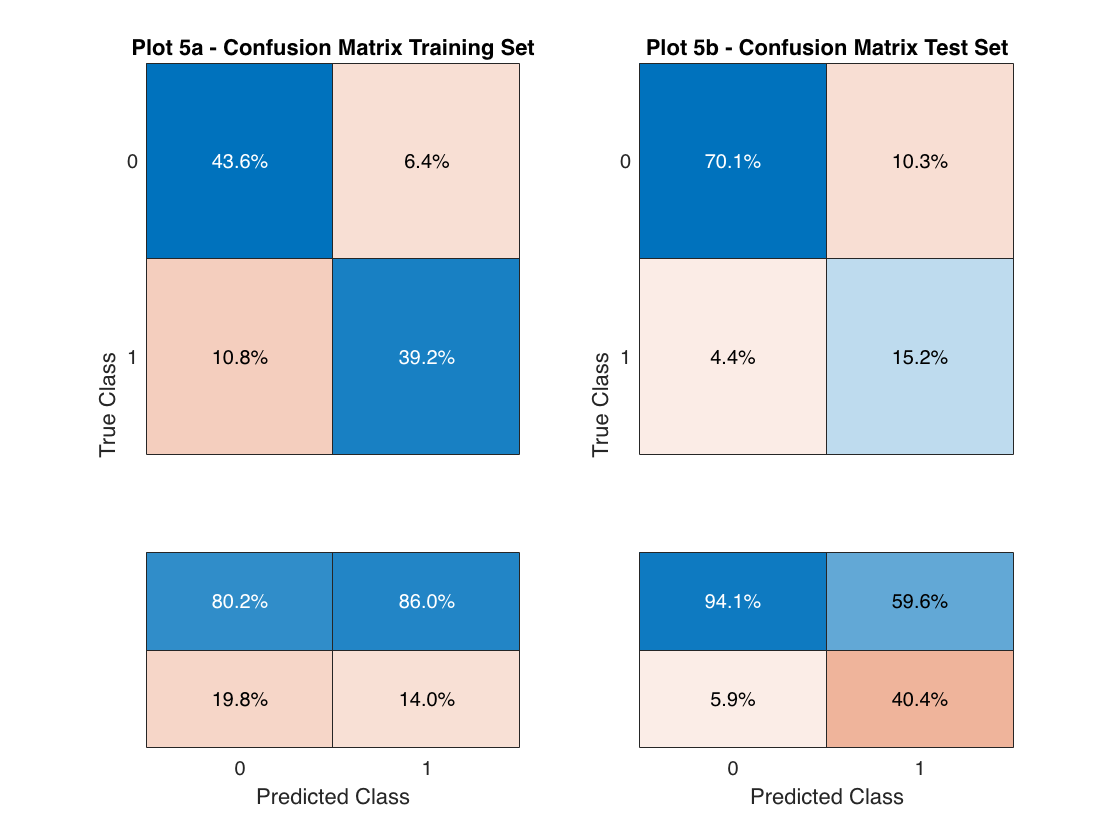

labels_tr = predict(Model_T, train); % predicted labels 
figure();
subplot(1,2,1)
conf_chart_2 = confusionchart(train.Stay, labels_tr, 'Normalization','total-normalized', 'ColumnSummary','column-normalized'); % confusion chart
conf_chart_2.Title = "Plot 5a - Confusion Matrix Training Set";
labels_te = predict(Model_T, test); % predicted labels 
subplot(1,2,2)
conf_chart_3 = confusionchart(test.Stay, labels_te, 'Normalization','total-normalized', 'ColumnSummary','column-normalized'); % confusion chart
conf_chart_3.Title = "Plot 5b - Confusion Matrix Test Set"; 

## ROC

`The receiver operator curve is another way to visualise true positives, false positives and total accuracy.`

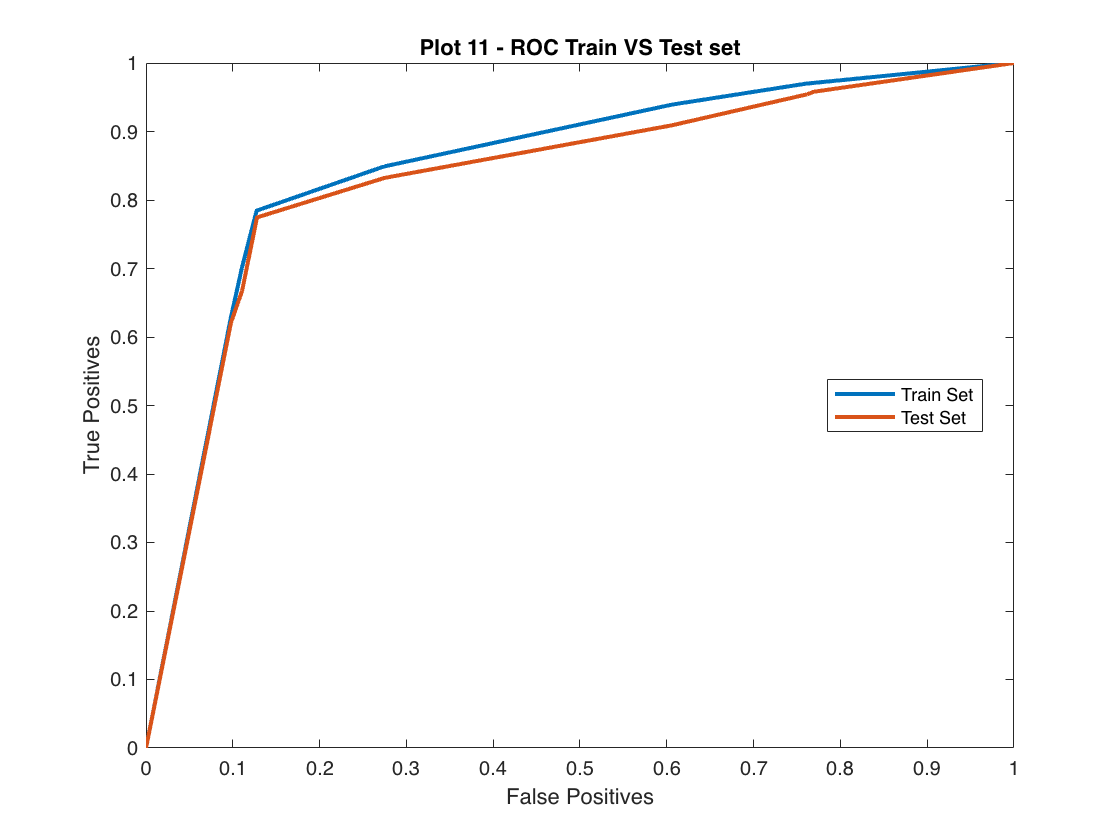

[~,score_train] = resubPredict(Model_T); % returns the scores (probabilities) of each class in the training set 
[label,score_test,node,cnum] = predict(Model_T, test); % returns the scores (probabilities) of each class in the test set 

[X, y, t, AUC] = perfcurve(train.Stay, score_train(:,2), 1); % ROC train set
[X_t, y_t, t_t, AUC_t] = perfcurve(test.Stay, score_test(:,2), 1); % ROC test set

figure();
plot(X, y, '-', 'LineWidth', 2)
hold on;
plot(X_t, y_t, '-', 'LineWidth', 2)
xlabel('False Positives');
ylabel('True Positives');
title('Plot 11 - ROC Train VS Test set')
legend('Train Set', 'Test Set', 'Location', 'best')

`Our model seems to reach an optimal True Positive / False Positive rate at aorund 12% false positives. This is in line with what we saw in the plot above (plot 5) and follows the same considerations. `

## `Model predictors `

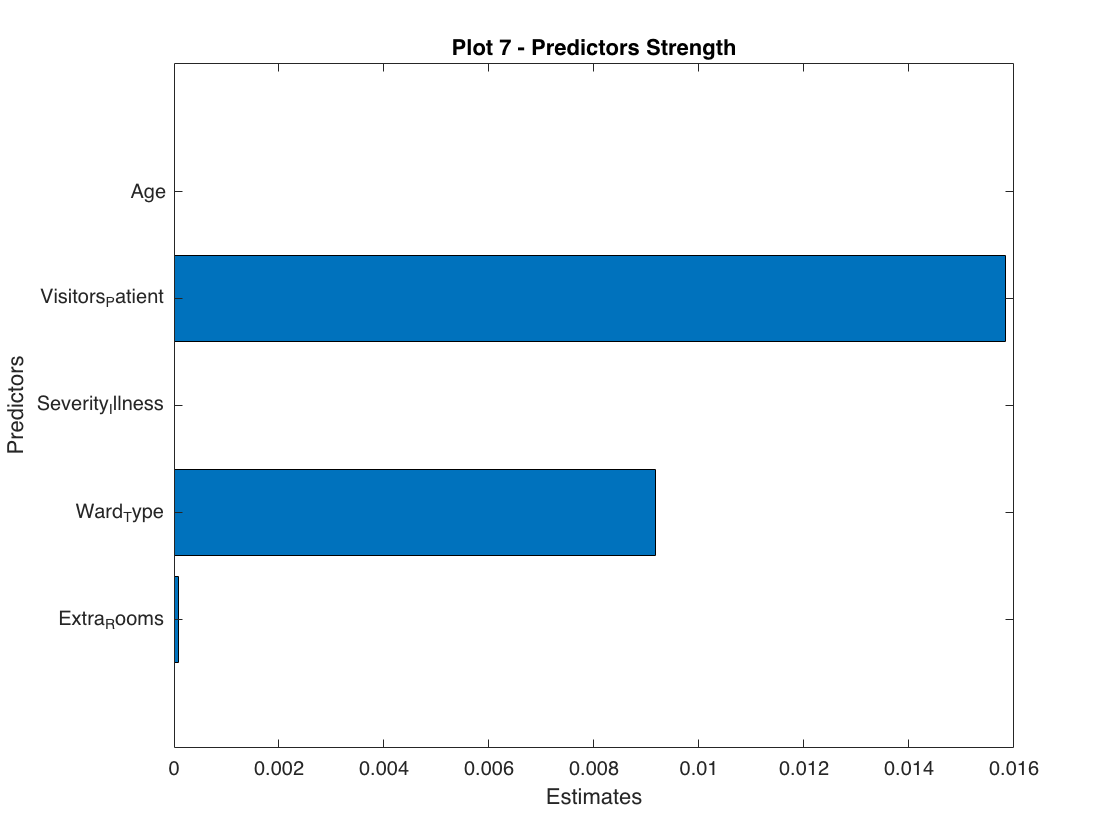

features_imp = predictorImportance(Model_T);
figure
barh(features_imp);
title('Plot 7 - Predictors Strength');
xlabel('Estimates');
ylabel('Predictors');
h = gca;
h.YTickLabel = Model_T.PredictorNames;

`The main predictors used by the model are the two that had the highest correlation to our target variable, as seen in our correlation matrix during the pre-processing. `

## `Viewing the Tree`

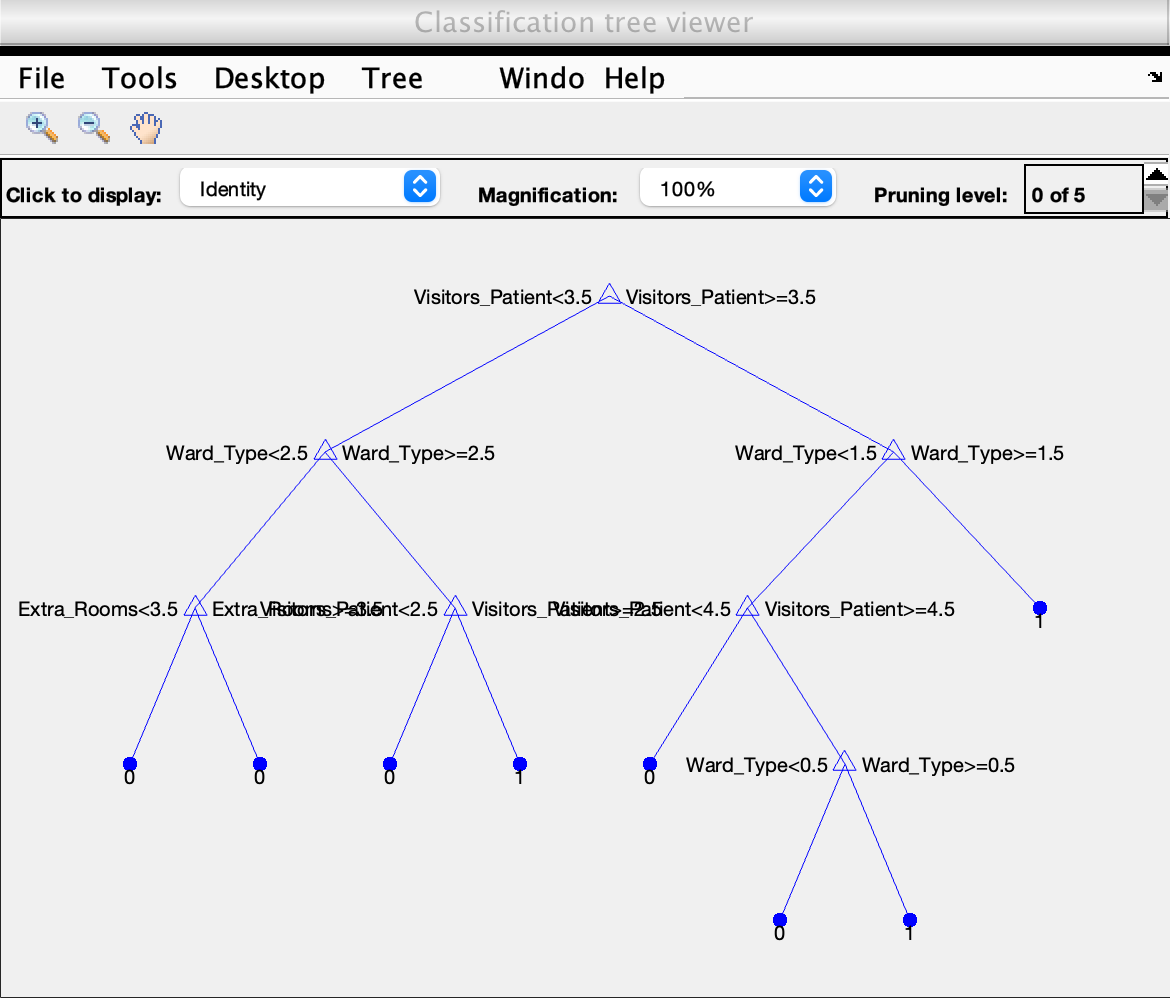

view(Model_T, "Mode","graph")

## Plots

## `Prior Probabilities - Train and Test set`

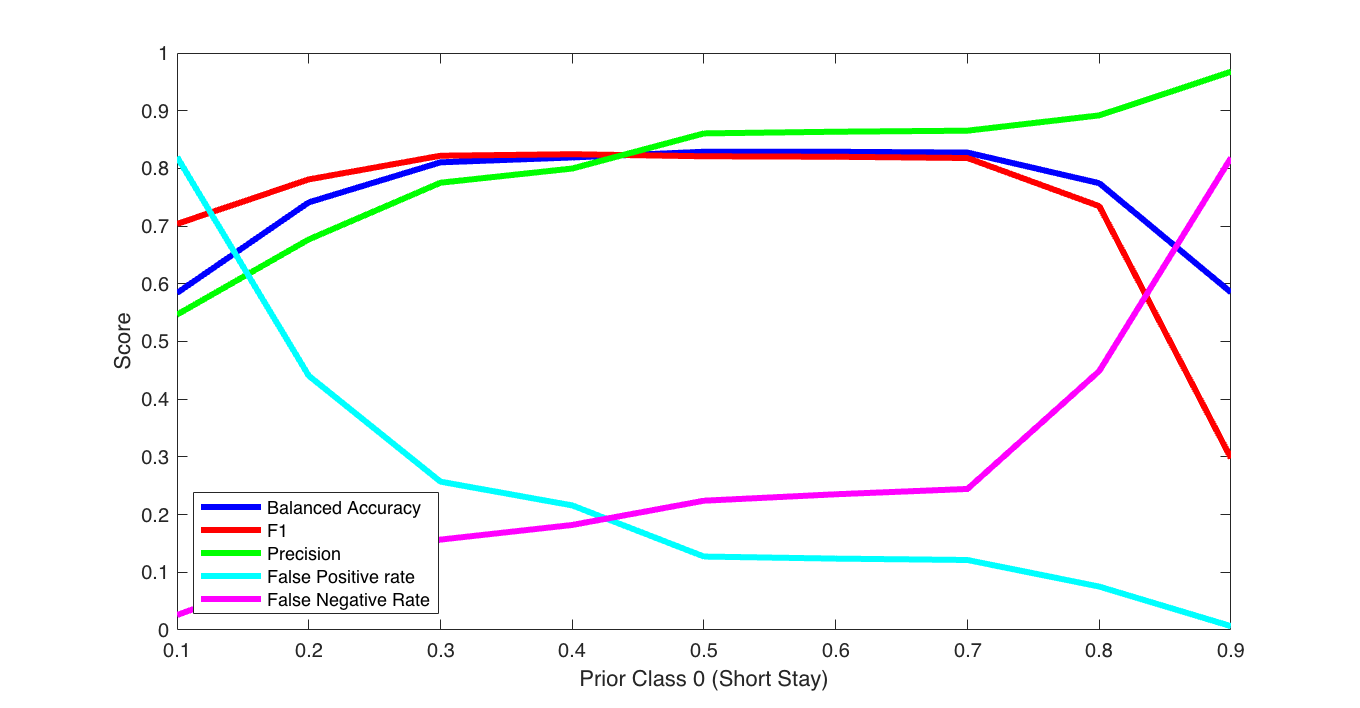

prior_x = [0.9:-0.1:0.1]; % prior probabilty for class 0 (Negative / "Short Stay")
prior_y = [0.1:0.1:0.9]; % prior probabilty for class 1 (Positive/ "Long Stay")
train_loss = zeros(1, numel(prior_x)); % store train here
test_loss = zeros(1, numel(prior_x)); % store test loss
train_ba = zeros(1, numel(prior_x));  % store train balanced accuracy 
test_ba = zeros(1, numel(prior_x));  % store test balanced accuracy 
train_pr = zeros(1, numel(prior_x)); % store train precision
test_pr = zeros(1, numel(prior_x)); % store test precision
train_f1= zeros(1, numel(prior_x)); % store train f1
test_f1= zeros(1, numel(prior_x)); % store train f1
train_fpr= zeros(1, numel(prior_x)); % store train fpr
train_fnr= zeros(1, numel(prior_x)); % store train fpnr

for i  = 1:length(prior_x)
    prior = [prior_x(i), prior_y(i)];
    Model = fitctree(train, 'Stay','MaxNumSplits', 30, 'MinLeafSize', 4, 'Prior', prior);
    train_loss(i) = loss(Model, train, 'Stay'); % train loss
    test_loss(i) = loss(Model, test, 'Stay'); % test loss 
    train_ba(i) = balanced_accuracy(Model, train); % train balanced accuracy
    test_ba(i) = balanced_accuracy(Model, test); % test balanced accuracy
    train_f1(i) = f1(Model, train); % train f1
    test_f1(i) = f1(Model, test); % test f1
    train_pr(i) = precision(Model, train); % train sensitivity
    test_pr(i) = precision(Model, test); % train specificity
    train_fpr(i) = fpr(Model, test); % false positive rate
    train_fnr(i) = fnr(Model, test); % false negative rate
 
end

figure();
set(gcf,'position',[10, 10 , 2500 , 1300]);
% subplot 1 
plot(prior_x, train_ba, '-b', 'LineWidth',3);
hold on;
plot(prior_x, train_f1, '-r', 'LineWidth',3);
plot(prior_x, train_pr, '-g', 'LineWidth',3);
plot(prior_x, train_fpr, '-c', 'LineWidth',3);
plot(prior_x, train_fnr, '-m', 'LineWidth',3);
xlabel('Prior Class 0 (Short Stay)');
ylabel('Score');
legend('Balanced Accuracy', 'F1','Precision','False Positive rate', 'False Negative Rate', 'Location', 'southwest');

function f1 = f1_bayes(params,X,Y) %custom loss function for to optmize model on f1 with Bayesian optimization
        % this is the function fitted in the last optimization
        tree=fitctree(X,Y,'MaxNumSplits',params.MaxNumSplit,'MinLeafSize',params.MinLeaf, 'KFold',10, 'Prior', [0.7, 0.3]); % 10 fold crossvalidated model with 70/30 priors.
        predicted_labels = kfoldPredict(tree);
        conf_chart = confusionmat(table2array(X(:, end)), predicted_labels); % confusuion chart. 
        prec = conf_chart(2,2)/ (conf_chart(1,2) + conf_chart(2,2)); % precision
        rec = conf_chart(2,2)/ (conf_chart(2,1) + conf_chart(2,2));  % recall
        f1 = 1 -(2 * ((prec * rec)/(prec + rec))); % inverse of f1 (to minimize)
end